## 1. Representación de un filtro en escala lineal y logarítmica

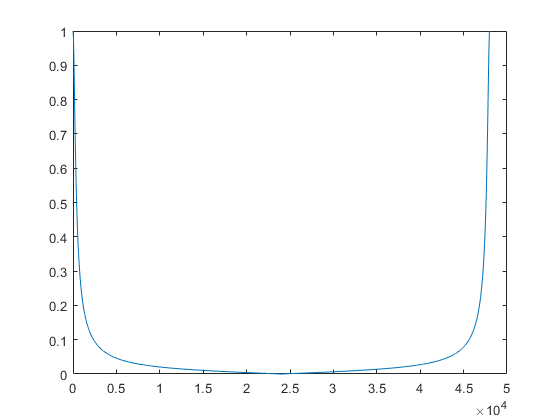

fs=48e3; f=0:fs-1;
plot(f,abs(H))

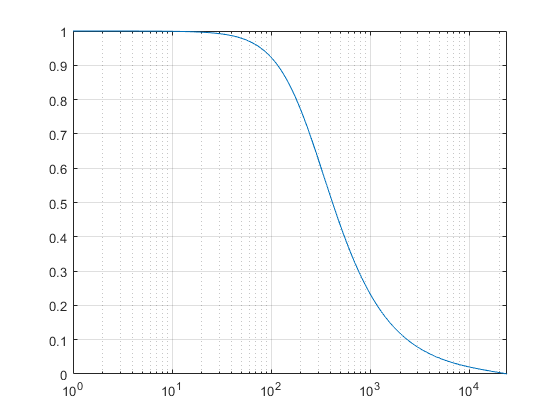

semilogx(f,abs(H))
grid on, axis([0 fs/2 0 1]);

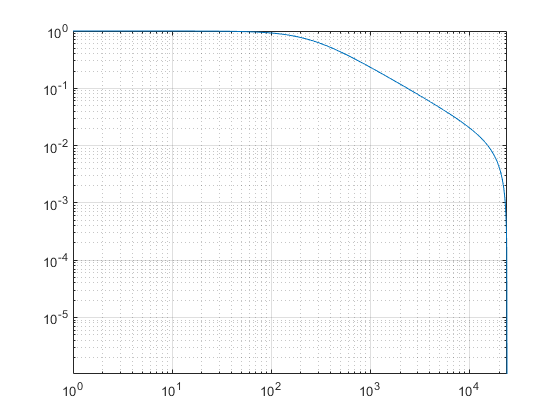

loglog(f,abs(H))
grid on, axis([0 fs/2 0 1]);

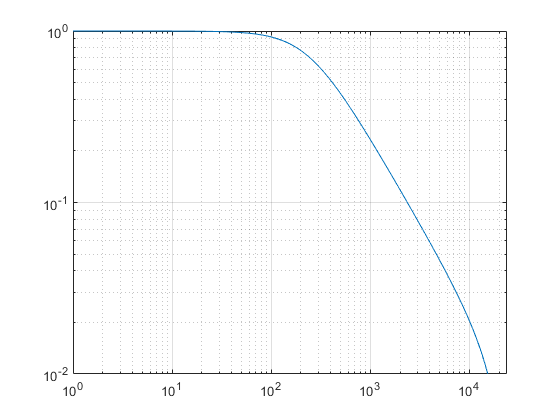

loglog(f,abs(H))
% el axis pertenece a los valores equivalentes a -40dB (0.01) y 0dB (1)
% que vienen de 20*log(x)=valordB. 
grid on, axis([0 fs/2 0.01 1]); 

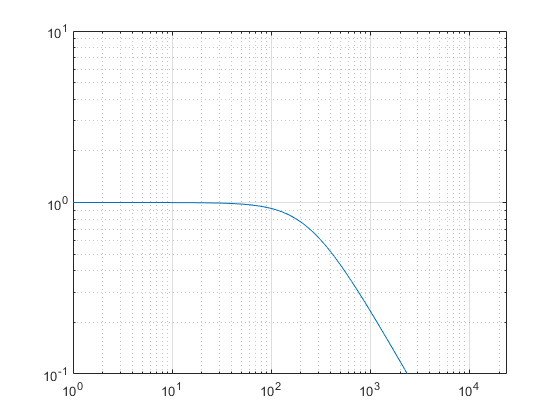

loglog(f,abs(H)) 
% ahora para que quede en el medio, pondría en la escala entre 20dB y -20dB (con sus valores equivalentes)
grid on, axis([0 fs/2 0.1 10]); 

a1=20*log10(1), a2=20*log10(.1)

a1 = 0

a2 = -20

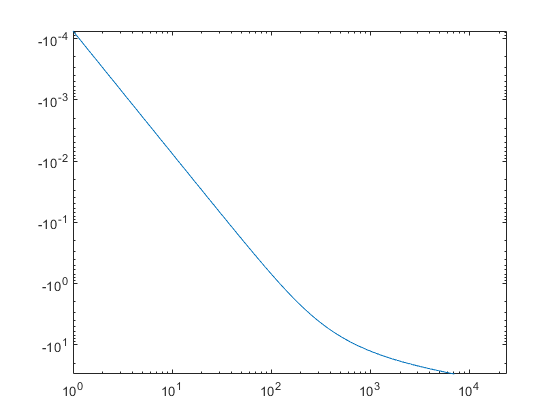

loglog(f,20*log10(abs(H)))
axis([0 fs/2 -30 10])

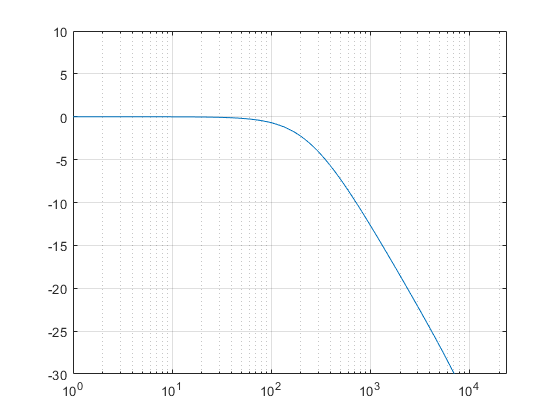

semilogx(f,20*log10(abs(H)))
axis([0 fs/2 -30 10]); grid on

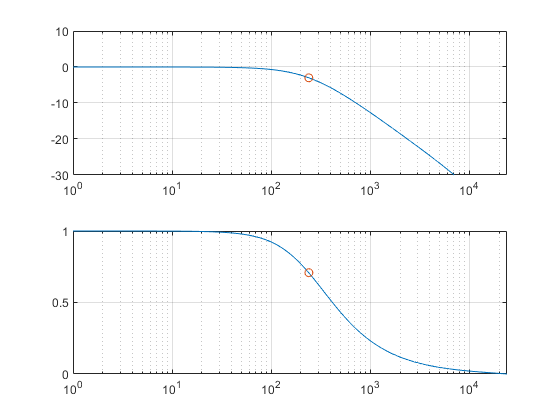

subplot(2,1,1);
semilogx(f,20*log10(abs(H)),240,20*log10(abs(H(240))),'o')
axis([0 fs/2 -30 10]), grid on
subplot(2,1,2);
semilogx(f,abs(H),240,abs(H(240)),'o')
grid on, axis([0 fs/2 0 1]);

## 2. Filtrar una señal multiplicando su espectro por la respuesta en frecuencia del filtro H(f)

a. Generar una variable x(t) de duración 1 segundo que tenga 5 componentes de frecuencia

fs=48e3; t=0:fs^(-1):(fs-1)*(fs^(-1));
xt=0*t;
for n=0:4
    fn=24*10^(n/2);
    xt=xt+sin(2*pi*fn*t);
end

b. Graficar la señal (x) y su espectro (X) para obtener los dos gráficos de la izquierda de la figura 3. Revisar la escala

horizontal temporal del gráfico superior para verificar que se obtiene la misma señal.

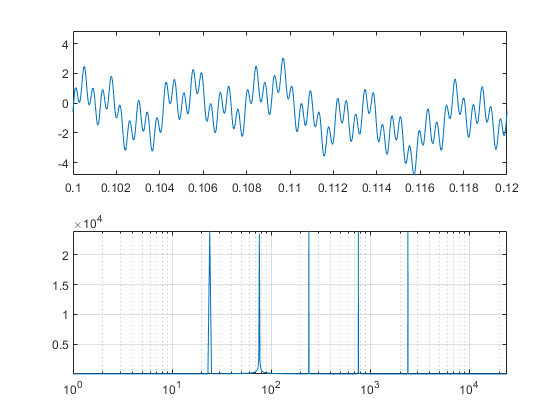

subplot(2,1,1)
plot(t,xt)
axis([0.1 0.12 -inf inf])
xf=(0:length(xt)-1)/length(xt)*fs;
X=fft(xt);
subplot(2,1,2)
semilogx(xf,abs(X))
%semilogx(xf,20*log10(abs(X)))
axis([0 fs/2 -inf inf]), grid on

%No se como lograr que me quede en dB el eje Y.

c. Obtener el espectro de la señal de salida (Y) multiplicando punto a punto la variable H y la variable X.

Y=(X.').*(H.');

d. Graficar el espectro en dB de la señal de salida

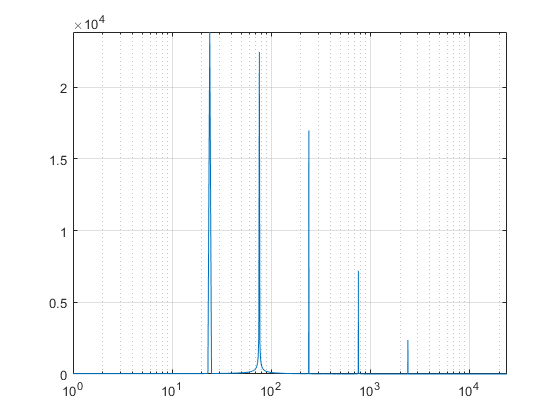

subplot(1,1,1)
semilogx(xf,abs(Y))
axis([0 fs/2 -inf inf]), grid on % Lo mismo que arriba, no le encontre la vuelta.

e. Obtener la señal de salida temporal (y), calculando la antitransformada de (Y) mediante la función ifft(). y graficarla para

obtener la curva en color rojo 

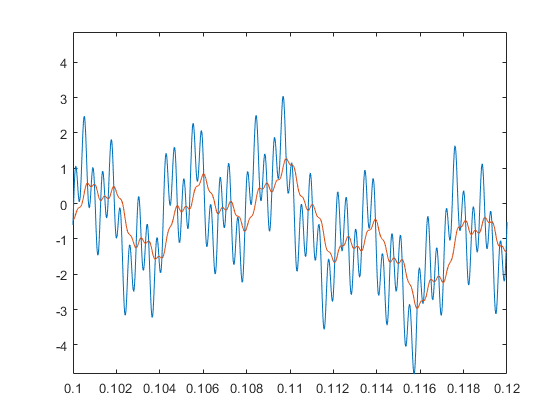

yt=ifft(Y);
plot(t,xt,t,yt)
axis([0.1 0.12 -inf inf])

f. Escuchar la señal original y la filtrada.

sound(xt/5,fs);
pause(2);
sound(yt/5,fs);

## 3. Cargar archivo de audio uno.wav y filtrarlo con H. Escuchar los resultados comparados.

UNO=fft(uno);
UNOF= UNO.*H.';
unof=ifft(UNOF);

sound(uno,fs);
pause(2);
sound(unof,fs);

## 4. Generar un impulso de un segundo de duración y verificar que su fft() es un espectro plano. Observar las fases.

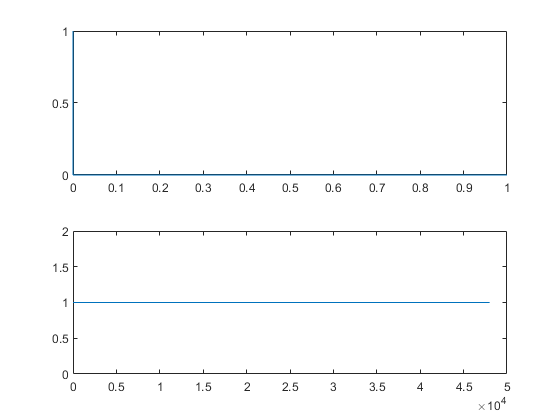

fs=48e3;
t=0:(1/fs):1-(1/fs);
impulso=zeros(length(t),1);
impulso(1)=1;



I=fft(impulso);
f=(0:length(t)-1)/length(t)*fs;
subplot(2,1,1);
plot(t,impulso);
subplot(2,1,2);
plot(f,abs(I));

**5. Exportar el impulso como wav, abrir desde un editor de audio, filtrar y guardar como "rtaImpulso.wav". Cargar en**

**MATLAB y observar la fft() de la respuesta al impulso. Podrá verse el perfil del filtro utilizado, y también cómo afecta las**

**fases**

audiowrite('impulso.wav',impulso,fs);

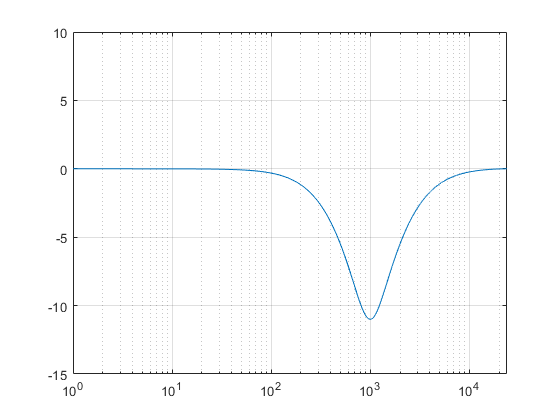

[rtalimpulso,fs]=audioread('rtalimpulso.wav');
H=fft(rtalimpulso);
f=0:fs-1;
subplot(1,1,1);
semilogx(f,20*log10(abs(H)));
axis([0 fs/2 -15 10]), grid on 

## 6. Aplicar el filtro anterior a un audio (uno.wav)

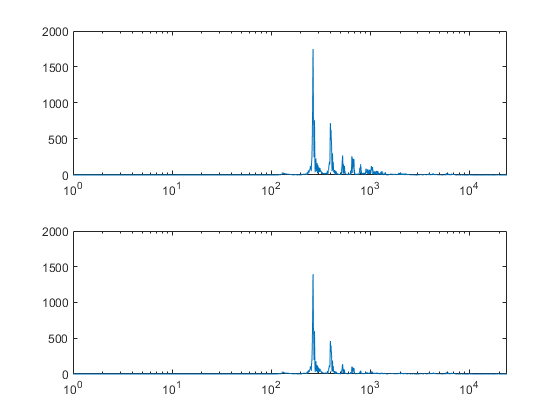

[uno,fs]=audioread('uno1.wav');
UNO=fft(uno);
UNOF= UNO.*H;
unof=ifft(UNOF);
subplot(2,1,1);
semilogx(f,abs(UNO));
axis([0 fs/2 0 2e3])
subplot(2,1,2);
semilogx(f,abs(UNOF))
axis([0 fs/2 0 2e3])

sound(uno,fs);
pause(2);
sound(unof,fs);

## 7. Repetir con un EQ gráfico y aplicarlo al audio uno.wav y a x(t), escuchando los resultados.

[ireq,fs]=audioread('ireq.wav');
Heq=fft(ireq);
% con audio "uno"
UNOeq= UNO.*Heq;
unoeq=ifft(UNOeq);
sound(uno,fs);
pause(2);
sound(unoeq,fs);

% con x(t)

X=fft(xt);
Xeq= X.'.*Heq;
xeq=ifft(Xeq);
sound(xt,fs);
pause(2);
sound(xeq,fs);

## 8. Repetir el ejercicio 2, pero utilizar la función conv(x,h) para obtener la señal filtrada y(t).

h=ifft(H);
yt=conv(h,xt);
sound(xt,fs);
pause(2);
sound(yt,fs);

## 9. Obtener el filtrado del audio uno.wav utilizando la respuesta al impulso de un filtro a elección (H original o uno obtenido

## de un editor de audio).

[ireq,fs]=audioread('ireq.wav');
unoeq2=conv(uno,ireq);

sound(uno,fs);
pause(2);
sound(unoeq2,fs);

## 10. Generar una respuesta al impulso que corresponda a un impulso desplazado medio segundo (24000 muestras).

## Realizar la convolución entre el audio uno.wav y la respuesta al impulso creada. Plotear el audio original y el procesado

## (tener en cuenta que será necesario definir dos variables de tiempo ya que tendrán diferente duración). Escuchar los

## resultados.

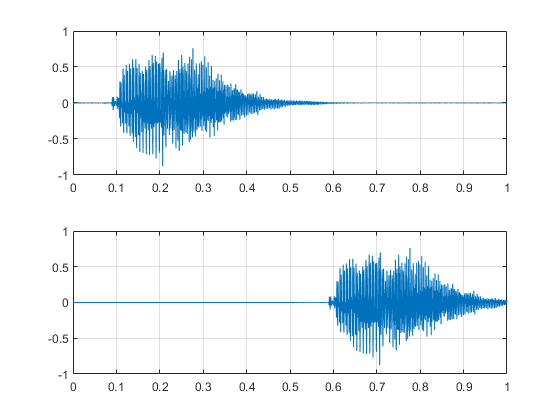

% generacion de la respuesta a un impulso desplazdo 0.5 segundos.

t1=0:(1/fs):1.5-(1/fs);
ridelay05=zeros(length(t),1);
ridelay05(24e3+1)=1;

% convolucion

unodelay05=conv(ridelay05,uno);

%ploteo

subplot(2,1,1);
plot(t,uno);
axis([0 1 -1 1]); grid on
t2=0:(1/fs):(length(unodelay05)-1)*(1/fs); % para graficar genero t2 con esa duracion.
subplot(2,1,2);
plot(t2,unodelay05);
axis([0 1 -1 1]); grid on

% escucha

sound(uno,fs);
pause(2);
sound(unodelay05,fs);

## 11. Generar una respuesta al impulso que corresponda a un eco simple mediante una secuencia de cuatro impulsos de

## amplitudes 0.8, 0.5, 0.3, 0,1 ubicados en t=0, t=0.3, t=0.6, t=0.9 segundos. Realizar la convolución entre el audio uno.wav

## y la respuesta al impulso creada. Plotear el audio original y el procesado (tener en cuenta que será necesario definir dos

## variables de tiempo ya que tendrán diferente duración). Plotear los resultados

## Repetir con clap.wav, plotear los resultados y escuchar.

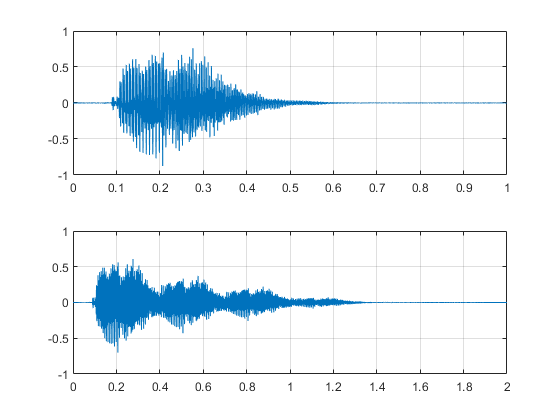

% generacion de ri del eco

teco=0:(1/fs):2-(1/fs);
rieco=zeros(length(teco),1);

rieco(1)=0.8;
rieco(14401)=0.5;
rieco(28801)=0.3;
rieco(43201)=0.1;

% convolucion

unoeco=conv(uno,rieco);

%ploteo
subplot(2,1,1);
plot(t,uno);
axis([0 1 -1 1]); grid on
subplot(2,1,2);
t2eco=0:(1/fs):(length(unoeco)-1)*(1/fs);
plot(t2eco,unoeco);
axis([0 2 -1 1]); grid on

% escucha

sound(uno,fs);
pause(2);
sound(unoeco,fs);

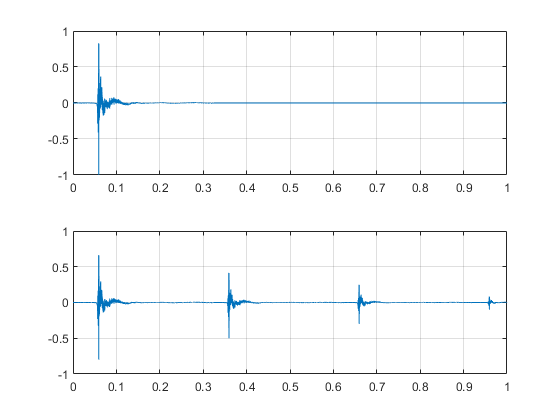

% con clap

ecoclap=conv(yclap,rieco);

% ploteo

subplot(2,1,1);
plot(t,yclap);
axis([0 1 -1 1]); grid on
subplot(2,1,2);
t2clap=0:(1/fs):(length(ecoclap)-1)*(1/fs);
plot(t2clap,ecoclap);
axis([0 1 -1 1]); grid on

% escucha

sound(yclap,fs);
pause(2);
sound(ecoclap,fs);

## 12. Generar una respuesta al impulso que corresponda a una reverb artificial muy sencilla con los datos de tiempo y

## amplitud de la siguiente tabla.

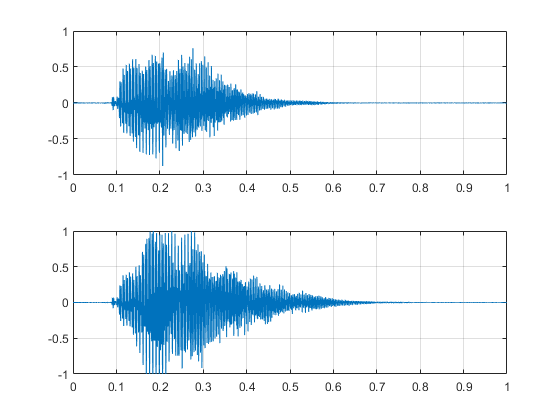

% generacion de respuesta al impulso de una reverb
treverb=0:(1/fs):1.5-(1/fs);
rireverb=zeros(length(treverb),1);

rireverb(1)=0.8;
rireverb(1441)=0.4;
rireverb(2161)=0.4;
rireverb(2641)=0.4;
rireverb(3841)=0.3;
rireverb(5041)=0.3;
rireverb(6721)=0.2;
rireverb(8641)=0.2;
rireverb(10081)=0.15;

% convolucion

unoreverb=conv(rireverb,uno);

% ploteo

subplot(2,1,1);
plot(t,uno);
axis([0 1 -1 1]); grid on
subplot(2,1,2);
t2reverb=0:(1/fs):(length(unoreverb)-1)*(1/fs);
plot(t2reverb,unoreverb);
axis([0 1 -1 1]); grid on

% escucha

sound(uno,fs);
pause(2);
sound(unoreverb,fs);

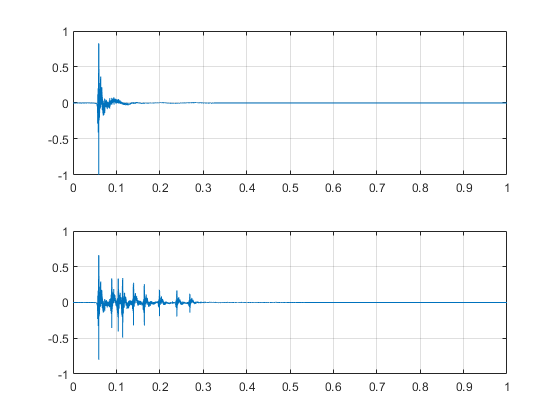

% con clap

clapreverb=conv(yclap,rireverb);

% ploteo
subplot(2,1,1);
plot(t,yclap);
axis([0 1 -1 1]); grid on
subplot(2,1,2);
t2clapreverb=0:(1/fs):(length(clapreverb)-1)*(1/fs);
plot(t2clapreverb,clapreverb);
axis([0 1 -1 1]); grid on

%escucha

sound(yclap,fs);
pause(2);
sound(clapreverb,fs);

## 13. Generar un impulso de 1 segundo de duración, ingresarlo a un editor de audio, programar allí una reverb y guardar la

## respuesta al impulso. Ingresar esta respuesta a MATLAB y plotear la respuesta al impulso

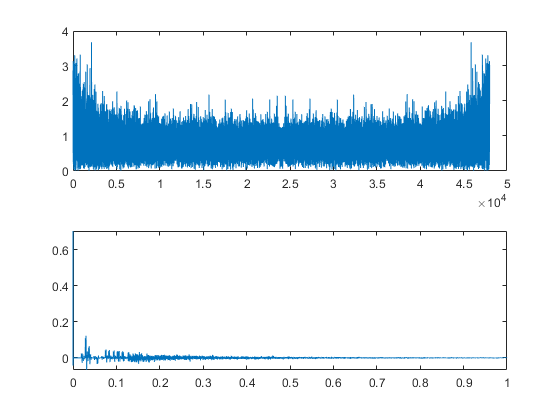

% usando el impulso generado en el punto 5
[reverbri,fs]=audioread('reverbri.wav');

RH=fft(reverbri);
subplot(2,1,1)
plot(abs(RH));
subplot(2,1,2);
plot(t,reverbri);

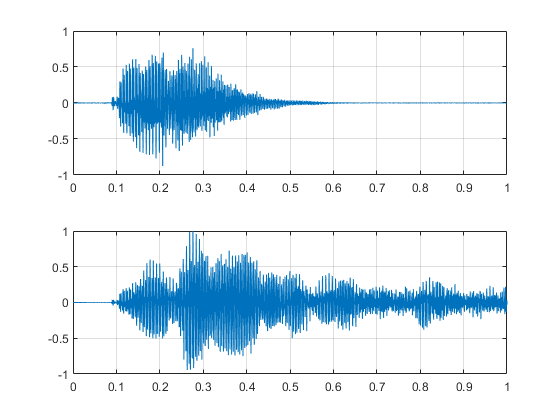

% uno con reverb

unoreverb2=conv(uno,reverbri);

%ploteo

subplot(2,1,1);
plot(t,uno);
axis([0 1 -1 1]); grid on
subplot(2,1,2);
t2unoreverb2=0:(1/fs):(length(unoreverb2)-1)*(1/fs);
plot(t2unoreverb2,unoreverb2);
axis([0 1 -1 1]); grid on

%escucha

sound(uno,fs);
pause(2);
sound(unoreverb2,fs);

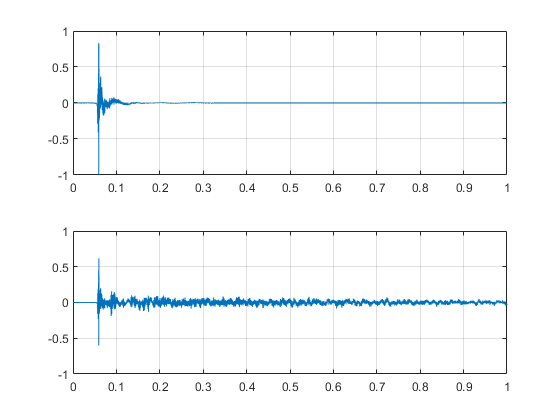



% con clap

clapreverb2=conv(yclap,reverbri);

% ploteo

subplot(2,1,1);
plot(t,yclap);
axis([0 1 -1 1]); grid on
subplot(2,1,2);
t2clapreverb2=0:(1/fs):(length(clapreverb2)-1)*(1/fs);
plot(t2clapreverb2,clapreverb2);
axis([0 1 -1 1]); grid on

% escucha

sound(yclap,fs);
pause(2);
sound(clapreverb2,fs);